# Electric Dipole Moment and Radiation Power

This example finds the average radiation power of two attracting charges moving in an elliptical orbit (an *electric dipole*).

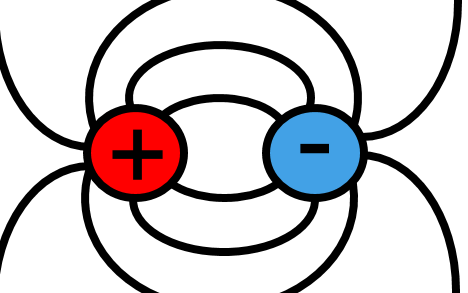

## Common Center of Mass

The two opposite charges, `e1` and `e2`, form an electric dipole. The masses of the charged particles are `m1` and `m2`, respectively. For the common center of mass `m1*r1 + m2*r2 = 0`, where `r1` and `r2` are distance vectors to the charged particles. The distance between charged particles is `r = r1 - r2`.

syms m1 m2 e1 e2 r1 r2 r
[r1,r2] = solve(m1*r1 + m2*r2 == 0, r == r1 - r2, r1, r2)

## Dipole Moment

Find the dipole moment of this system:

d = e1*r1 + e2*r2;
simplify(d)

## Radiation Power per Unit of Time

According to the Larmor formula, the total power radiated in a unit of time is $J = \frac{2}{3c^3} \ddot d^2$, or, in terms of the distance between the charged particles, $J = \frac{2}{3c^3}\frac{m1m2}{m1 + m2} \left(\frac{e1}{m1} - \frac{e2}{m2} \right)^2 \ddot r^2$. Here dot means a time derivative. Coulomb's law $m \ddot r = -\frac{\alpha}{r^2}$ lets you find the values of acceleration $\ddot r$ in terms of the reduced mass of the system, $m = \frac{m1m2}{m1 + m2}$, and the product of the charges of the particles, $\alpha = \left|e1e2\right|$.

alpha = sym('alpha');
syms m c
m = m1*m2/(m1 + m2);
r2 = -alpha/(m*r^2);

J = simplify(subs(2/(3*c^3)*d^2, r, r2))

## Parameters of the Elliptical Orbit

The major semiaxis a and eccentricity $\epsilon$ of an elliptical orbit are given by the following expressions, where `E` is the total orbital energy, and $L = mr^2 \dot \phi$ is the angular momentum.

syms E L phi
a = alpha/(2*E)
eccentricity = sqrt(1-2*E*L^2/(m*alpha^2))

The equation of an elliptical orbit, $1 + \epsilon \cos \phi = a \left(1 - \epsilon^2 \right)/r$, lets you express the distance `r` in terms of the angle `phi`.

r = a*(1 - eccentricity^2)/(1 + eccentricity*cos(phi));

## Averaged Radiation Power

The average radiation power of two charged particles moving in an elliptical orbit is an integral of the radiation power over one full cycle of motion, normalized by the period of motion, $J_{avg} = 1/T \int^T_0 J\,dt$. The period of motions `T` is

T = 2*pi*sqrt(m*a^3/alpha);

Changing the integration variable `t` to `phi`, you get the following result. Use the `simplify` function to get a shorter integration result. Here, use `subs` to evaluate `J`.

J = subs(J);
Javg = simplify(1/T*int(J*m*r^2/L, phi, 0, 2*pi))

## If One Particle is Much Heavier Than the Other

Estimate the average radiation power of the electric dipole with one particle much heavier than the over, `m1>>m2`. For this, compute the limit of the expression for radiation power, assuming that `m1` tends to infinity.

limJ = limit(Javg, m1, Inf);
simplify(limJ)

*Copyright 2014-2016 The MathWorks, Inc.*